- Load Audio

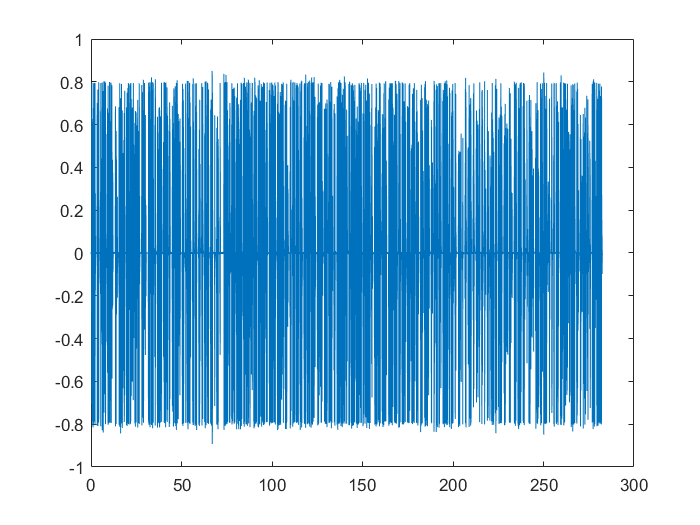

[orig_audio, orig_Fs] = audioread("audio_sample_2.mp3");
% downsample_ratio = 1;
% orig_audio = downsample(orig_audio, orig_Fs / downsample_ratio);
% orig_Fs = orig_Fs / downsample_ratio;
t = (1/orig_Fs) * (0:length(orig_audio)-1);
plot(t, orig_audio);

2. Generating Noise

% Adding noise
% [noise_sample, noise_Fs] = audioread("noise_sample_2-busy_street.mp3")
noisy_audio = awgn(orig_audio, 25);
sound(noisy_audio, orig_Fs)
% noise_sample = downsample(noise_sample, orig_Fs);

% 
% if numel(noise_sample(:,1)) > numel(orig_audio)
%     rand_noise_index = randi(abs(numel(noise_sample(:,1)) - numel(orig_audio)) + 1, 1, 1);
%     gen_noise = noise_sample(rand_noise_index:rand_noise_index + numel(orig_audio) - 1);
% else
%     orig_audio = orig_audio(1:length(noise_sample));
%     gen_noise = noise_sample(:,1);
%     gen_noise = gen_noise';
%     t = t(1:length(noise_sample));
% end

3. Adding Noise

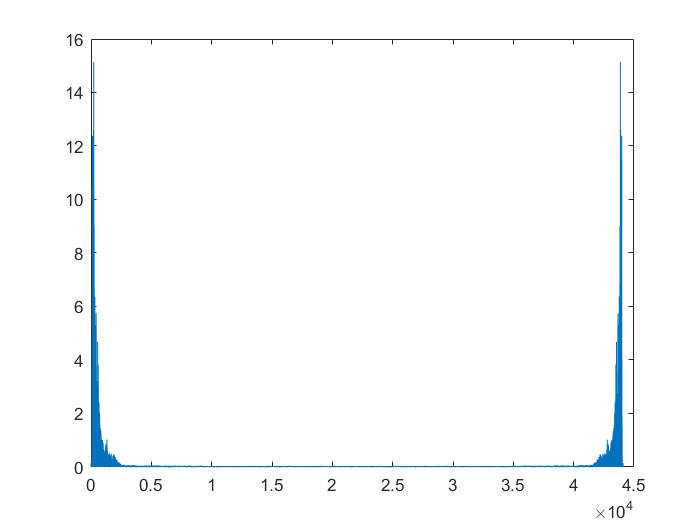

% orig_power = sum(orig_audio.^2);
% noise_weakness_factor = 4;
% noise_power = sum(gen_noise.^2) * noise_weakness_factor;
% % firfilt = dsp.FIRFilter;
% % firfilt.Numerator = fir1(11,0.4);
% % f_noise = firfilt(gen_noise )
% noisy_audio = orig_audio + sqrt(orig_power/noise_power) * gen_noise';

% Frequency Analysis
freq_values = fft(noisy_audio);
noise_len = length(noisy_audio);          % number of samples
f = (0:noise_len-1)*(orig_Fs/noise_len);     % frequency range
power = abs(freq_values).^2/noise_len;
plot(f, power)

% sound(noisy_audio, orig_Fs);
% sound(f_noise', orig_Fs)
plot(t, f_noise);

Unrecognized function or variable 'f_noise'.

plot(t, noisy_audio)

4. Butterworth Bandpass Filter

lower_freq = 300;
upper_freq = 4000;
% plot()
[b,a] = butter(5, [lower_freq,upper_freq] / (orig_Fs/2), "bandpass");
butter_audio = filter(b,a,noisy_audio);
plot(t, butter_audio)
% sound(butter_audio, orig_Fs)


5. Kaizer FIR Filter

% 
% Fs = orig_Fs;  % Sampling Frequency
% 
% Fstop1 = 200;      % First Stopband Frequency
% Fpass1 = 300;      % First Passband Frequency
% Fpass2 = 4000;     % Second Passband Frequency
% Fstop2 = 4500;     % Second Stopband Frequency
% Dstop1 = 0.001;    % First Stopband Attenuation
% Dpass  = 0.1;      % Passband Ripple
% Dstop2 = 0.001;    % Second Stopband Attenuation
% flag   = 'scale';  % Sampling Flag
% 
% % Calculate the order from the parameters using KAISERORD.
% [N,Wn,BETA,TYPE] = kaiserord([Fstop1 Fpass1 Fpass2 Fstop2]/(Fs/2), [0 ...
%                              1 0], [Dstop1 Dpass Dstop2]);
% 
% % Calculate the coefficients using the FIR1 function.
% b  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
% Hd = dfilt.dffir(b);
% kaiser_audio = filter(b,1,noisy_audio);
% % fzv = linspace(0, 1, 1000)*(Fs/2);                                          % Frequency Vector
% % freqz(b, 1024, fzv, Fs)      
% sound(kaiser_audio, orig_Fs);

5. Savitzky-Golay Filter

order = 9;
frame_len = 39;
sgolay_audio = sgolayfilt(butter_audio, order, frame_len);
% sound(sgolay_audio, orig_Fs);


6. Median Filter

% median_audio = medfilt1(sgolay_audio,10);
% sound(sgolay_audio, orig_Fs);
gaussian_filter = gausswin(3);
gaussian_audio = filter(gaussian_filter, 1, butter_audio);
sound(gaussian_audio, orig_Fs);

6. LMS Noise Cancellation

% aaa

% initial_coefficents = (firfilt.Numerator).'-0.01;
% step = 0.05; 
% lms = dsp.LMSFilter(12,'Method','Sign-Sign LMS',...
%    'StepSize',step,'InitialConditions',initial_coefficents);
% [clean, error] = lms(sgolay_audio, orig_audio);
% sound(error, orig_Fs)
